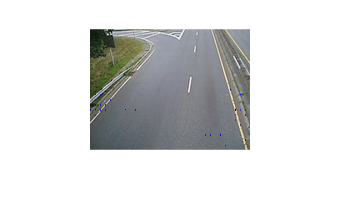

vidReader=VideoReader('viptraffic.avi');
opticFlow=opticalFlowHS;
nFrames=0;
while hasFrame(vidReader)
    frameRGB=readFrame(vidReader);
    frameGray=rgb2gray(frameRGB);
    flow=estimateFlow(opticFlow,frameGray);
    imshow(frameRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',25)
    hold off
    nFrames=nFrames+1;
end

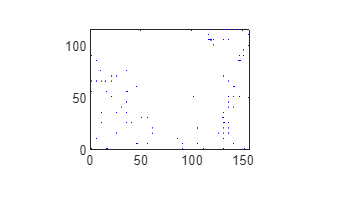


%display the horizontal and vertical
Vx = flow.Vx;
Vxo = flow.Vx.*0;
Vy = flow.Vy;
Vyo = flow.Vy.*0;
flowx = opticalFlow(Vx,Vyo);
flowy = opticalFlow(Vxo,Vy);
plot(flowx,'DecimationFactor',[5 5],'ScaleFactor',200);

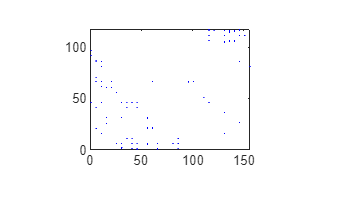

plot(flowy,'DecimationFactor',[5 5],'ScaleFactor',200);

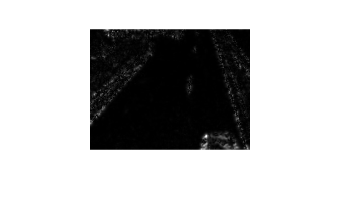


%display the magnitude
imshow(flow.Magnitude,[]);



%   Q3
opticFlow = opticalFlowLK('NoiseThreshold',0.009);
nFrames=0;
while hasFrame(vidReader)
    frameRGB=readFrame(vidReader);
    frameGray=rgb2gray(frameRGB);
    flow=estimateFlow(opticFlow,frameGray);
    imshow(frameRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',25)
    hold off
    nFrames=nFrames+1;
end
imshow(flow.Magnitude,[]);

% while hasFrame(vidReader)
%     frameRGB = readFrame(vidReader);
%     frameGray = im2gray(frameRGB);
%     flow = estimateFlow(opticFlow,frameGray);
%     imshow(frameRGB)
%     hold on
%     plot(flow,'DecimationFactor',[5 5],'ScaleFactor',10);
%     hold off
%     pause(10^-3)
% end